# Homework 2

## Constants

clc; clear ;
% Student number = 110230736
n = 6 ;

% Earth's radius 
r_earth = 6.3712 * 10^6; % m  

% The distance between the center of mass of the satellite and the Earth 
r = (r_earth/1000 + 800 + 5*n) * 1000; % m 

% Standard gravitational parameter of Earth
mu = 3.98601 * 10^14; % m^3 / s^2

% inclination
inc = 80 + 0.5 * n; % degree

% right ascension of the ascending node
omega = 2 * n; % degree

% argument of perigee
w = 0;

% Earth’s rotational velocity (It is assumed constant.)
w_earth = 7.29212 * 10^-5; % rad / s

% Number of samples
N = 6000;

% Sampling time
delta_t = 1; % s

% period 
T = 2 * pi * sqrt(r^3/mu);

% Necessary number of samples
N1_orbit = ceil(T) / delta_t;




## True annomaly and position vectors Calculation

theta_full = linspace(0, 360,N1_orbit); % True annomaly for full orbit
theta = theta_full(1:N);                % This part of true annomaly will be used
x_t = zeros(1,N);
y_t = zeros(1,N);
z_t = zeros(1,N);
% Compenents of position vector relative to the inertial frame
for i = 1:N
    % Correct formula for position components
    x_t(i) = r * (cosd(w + theta(i)) * cosd(omega) - sind(w + theta(i)) * sind(omega) * cosd(inc));
    y_t(i) = r * (cosd(w + theta(i)) * sind(omega) + sind(w + theta(i)) * cosd(omega) * cosd(inc));
    z_t(i) = r * (sind(w + theta(i)) *sind(inc));
end


## Plots ( 3D , x-y , x-z , y-z )

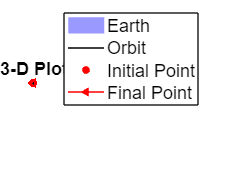

% 3-D
figure ;
[xs, ys, zs] = sphere(100) ; 
Xs = r_earth  * xs;
Ys = r_earth  * ys;
Zs = r_earth  * zs;
surf(Xs, Ys, Zs,FaceColor="[0, 0, 1]",EdgeColor="none",FaceAlpha="0.4");
hold on;

plot3(x_t,y_t,z_t,"-k")
grid on

plot3(x_t(1), y_t(1), z_t(1), 'o', 'MarkerEdgeColor', 'r', 'MarkerFaceColor', 'r');
plot3(x_t(end), y_t(end), z_t(end), 'r <-' , 'MarkerEdgeColor', 'r', 'MarkerFaceColor', 'r');

legend("Earth","Orbit","Initial Point","Final Point","FontSize", 15);
xlabel("X (m)","FontSize", 15);
ylabel("Y (m)","FontSize", 15);
zlabel ("Z (m)","FontSize", 15);
title("3-D Plot","FontSize", 15)

axis_range = 2 * r_earth;  % 2 times the Earth's radius
axis([-axis_range axis_range -axis_range axis_range -axis_range axis_range]);

% Equal axis scaling
axis equal;

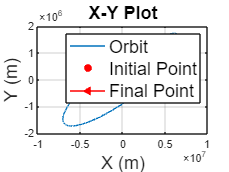


% X-Y
figure
plot(x_t,y_t)
hold on
plot(x_t(1), y_t(1), 'o', 'MarkerEdgeColor', 'r', 'MarkerFaceColor', 'r');
plot(x_t(end), y_t(end), 'r <-' , 'MarkerEdgeColor', 'r', 'MarkerFaceColor', 'r');
xlabel("X (m)","FontSize", 15);
ylabel("Y (m)","FontSize", 15);
title("X-Y Plot","FontSize", 15);
legend("Orbit","Initial Point","Final Point","FontSize", 15);
grid on

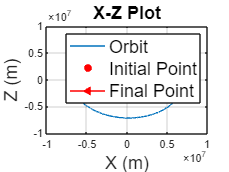


% X-Z
figure
plot(x_t,z_t)
hold on
plot(x_t(1), z_t(1), 'o', 'MarkerEdgeColor', 'r', 'MarkerFaceColor', 'r');
plot(x_t(end), z_t(end), 'r <-' , 'MarkerEdgeColor', 'r', 'MarkerFaceColor', 'r');
xlabel("X (m)","FontSize", 15);
ylabel("Z (m)","FontSize", 15);
title("X-Z Plot","FontSize", 15);
legend("Orbit","Initial Point","Final Point","FontSize", 15);
grid on

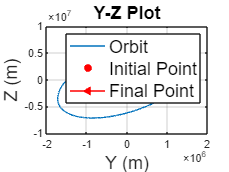


% Y-Z
figure
plot(y_t,z_t)
hold on
plot(y_t(1), z_t(1), 'o', 'MarkerEdgeColor', 'r', 'MarkerFaceColor', 'r');
plot(y_t(end), z_t(end), 'r <-' , 'MarkerEdgeColor', 'r', 'MarkerFaceColor', 'r');
xlabel("Y (m)","FontSize", 15);
ylabel("Z (m)","FontSize", 15);
title("Y-Z Plot","FontSize", 15);
legend("Orbit","Initial Point","Final Point","FontSize", 15);
grid on

## ECI to ECEF Coordinate Transformation

ecef = zeros(3,N);
altitude = zeros(1,N);
latitude = zeros(1,N);
longitude = zeros(1,N);


mjd_hw_date = mjuliandate(2024,04,13,23,59,00);
mjd_vernaleq = mjuliandate(2000,01,01,12,00,00);
mjd = mjd_hw_date - mjd_vernaleq;
eci_to_ecef = zeros(3,3,N);

for k=1:N
 alpha(k) = mod(w_earth * mjd * 86400 + w_earth * k,2*pi); % angle alpha (rad) is for transfer from ECI to ECEF
  % (ECI to ECEF)
    eci_to_ecef(:,:,k) = [cos(alpha(k))  sin(alpha(k)) 0;
                          -sin(alpha(k))  cos(alpha(k)) 0;
                            0            0           1];
    
    % Apply transformation to each ECI coordinate
    ecef(:,k) = eci_to_ecef(:,:,k) * [x_t(k); y_t(k); z_t(k)];
    r_earth_ecef(k) = norm(ecef(:, k));   % Distance from Earth center in m

    altitude(k) = r_earth_ecef(k) - r_earth;                                % meters 
    longitude(k) = (mod(atan2(ecef(2,k) , ecef(1,k)),2*pi)) * 180/pi;       % degree
    latitude(k) = (asin(ecef(3,k) / r_earth_ecef(k)))*180/pi;               % degree
    
end

## Plots of Altitude vs Time and Longitude- Latitude

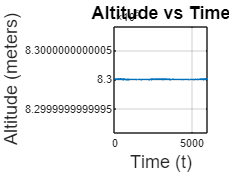

figure
plot(1:N , altitude);
xlabel("Time (t)","FontSize", 15);
ylabel("Altitude (meters)","FontSize", 15);
title("Altitude vs Time","FontSize", 15)
grid on

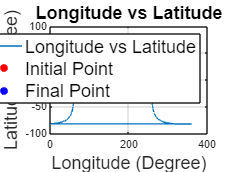


figure;
plot((longitude),(latitude));
hold on;
plot((longitude(1)), (latitude(1)),"rO","MarkerFaceColor","r")
plot((longitude(end)), (latitude(end)),"bO","MarkerFaceColor","b")
xlabel("Longitude (Degree)","FontSize", 15);
ylabel("Latitude (Degree)","FontSize", 15);
title("Longitude vs Latitude","FontSize", 15);
grid on
legend("Longitude vs Latitude", "Initial Point","Final Point","FontSize", 15)

## Magnetic Field Components using 'igrfmagm'

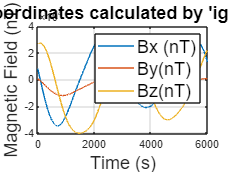

initial_date = datetime(2024,04,13,23,59,0);
time_vector = initial_date + seconds(1:N);
B_ecef = zeros(3,N);
B_eci = zeros(3,N);
B = zeros(3,N);
% NED to ECIF
for a= 1:N
 
     B(:,a) = igrfmagm(altitude(a), latitude(a), longitude(a), decyear(time_vector(a)), "13");
     
 
     % Calcuation of ECEF Coordinates
     % NED to ECEF DCM matrix :
     NED_to_ECEF_DCM = [-sind(latitude(a))*cosd(longitude(a)) ,    -sind(longitude(a)) ,  -cosd(latitude(a))*cosd(longitude(a));
                        -sind(latitude(a))*sind(longitude(a)) ,     cosd(longitude(a)) , -cosd(latitude(a))*sind(longitude(a));
                        cosd(latitude(a))                    ,         0               , -sind(latitude(a))]; 

     B_ecef(:,a) = NED_to_ECEF_DCM * B(:,a);

    
     %ECI coordinates of Magnetic Field
     B_eci(:,a) = eci_to_ecef(:,:,a)' *  B_ecef(:,a);
 end

% Plotting Magnetic Field Components in ECI
B_x_eci = B_eci(1,:);
B_y_eci = B_eci(2,:);
B_z_eci = B_eci(3,:);
    figure
    plot(1:N,B_x_eci)
    hold on
    plot(1:N,B_y_eci)
    plot(1:N,B_z_eci)
    legend("Bx (nT)","By(nT)","Bz(nT)","FontSize", 15)
    title("ECI coordinates calculated by 'igrfmagm'","FontSize", 15)
    grid on
    xlabel("Time (s)","FontSize", 15)
    ylabel("Magnetic Field (nT)","FontSize", 15)

## Magnetic Field Components using '‘wrldmagm’'

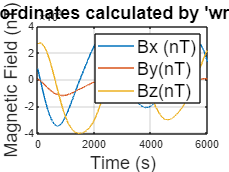

B_ecef2 = zeros(3,N);
B_eci2 = zeros(3,N);
B2 = zeros(3,N);

% NED to ECIF
for a= 1:N
  
    B2(:,a) = wrldmagm(altitude(a), latitude(a), longitude(a), decyear(time_vector(a)), "2020");
   
    % Calcuation of ECEF Coordinates
     % NED to ECEF DCM matrix :
     NED_to_ECEF_DCM_2 = [-sind(latitude(a))*cosd(longitude(a)) ,    -sind(longitude(a)) ,  -cosd(latitude(a))*cosd(longitude(a));
                        -sind(latitude(a))*sind(longitude(a)) ,     cosd(longitude(a)) , -cosd(latitude(a))*sind(longitude(a));
                        cosd(latitude(a))                    ,         0               , -sind(latitude(a))]; 

     B_ecef2(:,a) = NED_to_ECEF_DCM_2 * B2(:,a);

    
     %ECI coordinates of Magnetic Field
     B_eci2(:,a) = eci_to_ecef(:,:,a)' * B_ecef2(:,a);
end


% Plotting Magnetic Field Components in ECI
B_x_eci_2 = B_eci2(1,:);
B_y_eci_2 = B_eci2(2,:);
B_z_eci_2 = B_eci2(3,:);
figure
plot(1:N,B_x_eci_2)
hold on
plot(1:N,B_y_eci_2)
plot(1:N,B_z_eci_2)
legend("Bx (nT)","By(nT)","Bz(nT)","FontSize", 15)
title("ECI coordinates calculated by 'wrldmagm'","FontSize", 15)
grid on
xlabel("Time (s)","FontSize", 15)
ylabel("Magnetic Field (nT)","FontSize", 15)

## Difference between Two Methods

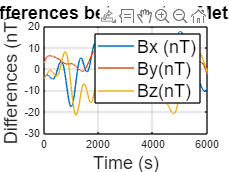

diff_Bx = B_x_eci - B_x_eci_2;
diff_By = B_y_eci - B_y_eci_2;
diff_Bz = B_z_eci - B_z_eci_2;

figure
plot(1:N,diff_Bx);
hold on
plot(1:N,diff_By);
plot(1:N,diff_Bz);
ylabel("Differences (nT)","FontSize", 15)
xlabel("Time (s)","FontSize", 15)
title("Differences between two Methods","FontSize", 15)
legend("Bx (nT)","By(nT)","Bz(nT)","FontSize", 15)
hold on
grid on